# **Predictions on Validation Data**

% Define folder path for the data
folder = ("C:\MathWorks\themoonrocks\ValidationResults_noTL_3C\Data\");
addpath('.\ValidationResults_noTL_3C\Data');

#### Defining directories

% Creating directories to save the predictions
myDir1 = 'ResultsVal/3C-noTL'; 
myDir2 = 'ConfusionMatrix';
myDir3 = 'ROCcurves';
if ~exist(myDir1, 'dir')
    mkdir(['./' myDir1 '/' myDir2])
    mkdir(['./' myDir1 '/' myDir3])
end

#### Plotting confusion matrix and ROCs for networks individually

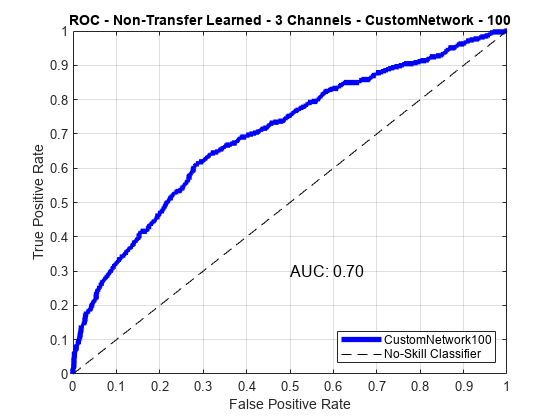

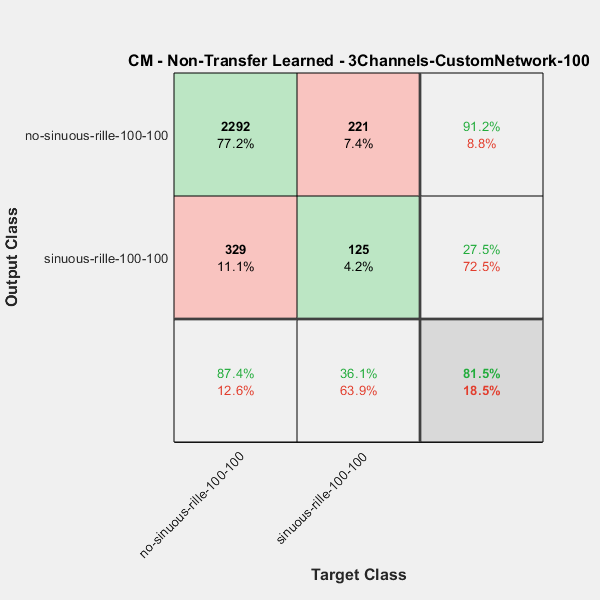

list = dir(strcat(folder,'*.mat'));
files = {list.name};
for i = 1:numel(files)
    try
        file = strcat(folder,files{i});
        fileName = files{i};
        data = load(fileName);
        [X, Y, ~, AUC] = perfcurve(data.ValidationLabels, data.score_Validation(:,2),...
            ['sinuous-rille-' num2str(data.patchSize) '-' num2str(data.patchSize)]);

        h = figure;
        plot(X, Y, 'b', 'LineWidth', 4); % ROC curve
        hold on;
        plot([0,1], [0,1], 'k--'); % No skill classifier
        xlabel('False Positive Rate');
        ylabel('True Positive Rate');
        grid on;
        % hLegend = legend(fileName(1:end-4) , 'No-Skill classifier', 'Location', 'southeast'); % Legend
        % legendPos = hLegend.Position;
        % text(legendPos(1), legendPos(2) + legendPos(4), sprintf('AUC: %.2f' , AUC), 'Units', 'normalized'); % AUC text
        legend(fileName(1:end-4), 'No-Skill Classifier', 'Location', 'southeast');
        text(0.5, 0.3, sprintf('AUC: %.2f' , AUC), 'Units', 'normalized', 'FontSize', 12);

        title(['ROC - Non-Transfer Learned - ' num2str(data.chnr) ' Channels - ' fileName(1:end-7) ' - ' num2str(data.patchSize)]);
        
        saveas(h, fullfile(['./' myDir1 '/' myDir3 '/', fileName(1:end-7) '-' num2str(data.chnr) 'C-noTL-' num2str(data.patchSize) '_ROC.png']));
        saveas(h, fullfile(['./' myDir1 '/' myDir3 '/', fileName(1:end-7) '-' num2str(data.chnr) 'C-noTL-' num2str(data.patchSize) '_ROC.fig']));
        close(h);
        
        fig = plotconfusion(data.ValidationLabels, data.predictedLabels_Validation);
        title(['CM - Non-Transfer Learned - ' num2str(data.chnr) 'Channels-' fileName(1:end-7) '-' num2str(data.patchSize)]);
        % title(['CM - Transfer Learned - ' num2str(data.chnr) ' Channels - ' fileName(1:end-7) ' - ' num2str(data.patchSize)]);

        saveas(fig, fullfile(['./' myDir1 '/' myDir2 '/', fileName(1:end-7) '-' num2str(data.chnr) 'C-noTL-' num2str(data.patchSize) '_CM.png']));
        saveas(fig, fullfile(['./' myDir1 '/' myDir2 '/', fileName(1:end-7) '-' num2str(data.chnr) 'C-noTL-' num2str(data.patchSize) '_CM.fig']));
        close(fig);

    catch ME
        disp(['Error processing ' fileName ': ' ME.message]);
    end
end

#### All ROCs together on same graph for comparision

list = dir(strcat(folder, '*.mat'));
files = {list.name};

% Create a figure outside the loop
fig = figure;
hold on; % Hold on to plot multiple curves

for i = 1:numel(files)
    try
        file = strcat(folder, files{i});
        fileName = files{i};
        data = load(file); % Make sure to load the file using its full path
        [X, Y, ~, AUC] = perfcurve(data.ValidationLabels, data.score_Validation(:,2), ...
            ['sinuous-rille-' num2str(data.patchSize) '-' num2str(data.patchSize)]);
        
        % Plot each ROC curve with a unique color and label
        plot(X, Y, 'LineWidth', 3, 'DisplayName', [fileName(1:end-4) ', AUC: ' sprintf('%.2f', AUC)]);
        
    catch ME
        disp(['Error processing ' fileName ': ' ME.message]);
    end
end

% Add the no skill classifier line, labels, legend, etc., after plotting all curves
plot([0, 1], [0, 1], 'k--', 'DisplayName', 'No-Skill Classifier');
xlabel('False Positive Rate');
ylabel('True Positive Rate');
title(['ROC Curves Comparision - Non-Transfer Learned - ' num2str(data.chnr) ' Channels']);
legend('Location', 'southeast'); % Automatically includes all plots with 'DisplayName'
grid on;
hold off;

% Save the figure
saveas(fig, fullfile(['./' myDir1 '/' myDir3 '/', 'All_ROC_' num2str(data.chnr) 'C-noTL.png']));
saveas(fig, fullfile(['./' myDir1 '/' myDir3 '/', 'All_ROC_' num2str(data.chnr) 'C-noTL.fig']));

% Close the figure if you don't need it open anymore
close(fig);

**Plotting all the ROC Curves of only specific patchSized Trained Models**

list = dir(strcat(folder, '*.mat'));
files = {list.name};

% Create a figure outside the loop
fig = figure;
hold on; % Hold on to plot multiple curves

for i = 1:numel(files)
    try
        if contains(files{i}, '200')
        file = strcat(folder, files{i});
        fileName = files{i};
        data = load(file); % Make sure to load the file using its full path
        [X, Y, ~, AUC] = perfcurve(data.ValidationLabels, data.score_Validation(:,2), ...
            ['sinuous-rille-' num2str(data.patchSize) '-' num2str(data.patchSize)]);
        
        % Plot each ROC curve with a unique color and label
        plot(X, Y, 'LineWidth', 3, 'DisplayName', [fileName(1:end-4) ', AUC: ' sprintf('%.2f', AUC)]);
        end

    catch ME
        disp(['Error processing ' fileName ': ' ME.message]);
    end
end

% Add the no skill classifier line, labels, legend, etc., after plotting all curves
plot([0, 1], [0, 1], 'k--', 'DisplayName', 'No-Skill Classifier');
xlabel('False Positive Rate');
ylabel('True Positive Rate');
title(['ROC Curves Comparision - Non-Transfer Learned - ' num2str(data.chnr) ' Channels - ' num2str(data.patchSize)]);
legend('Location', 'southeast'); % Automatically includes all plots with 'DisplayName'
grid on;
hold off;

% Save the figure
saveas(fig, fullfile(['./' myDir1 '/' myDir3 '/', num2str(data.patchSize) '_ROC_' num2str(data.chnr) 'C-noTL.png']));
saveas(fig, fullfile(['./' myDir1 '/' myDir3 '/', num2str(data.patchSize) '_ROC_' num2str(data.chnr) 'C-noTL.fig']));

% Close the figure if you don't need it open anymore
close(fig);